clear

MTOW = 32205 * 9.81;
WS = 3332;
Sref = MTOW/WS

Sref = 94.8172

discret = 0.01

discret = 0.0100

AR = 10;
Sweep = 0;
Taper = 1;

[T, a, P, rho] = atmosisa(35000*0.3048);
[T, a_sealevel, P, rho_sealevel] = atmosisa(0);

clear T P
V_stall_sealevel = sqrt(WS*2/(rho_sealevel*2.7))

V_stall_sealevel = 44.8867


fuselage_rad = 1.25;
twist = 0*pi/180;
panelnum = 50;
Cruise_Mach = 0.8

Cruise_Mach = 0.8000

Uinf = Cruise_Mach*a;
incidence = 6*pi/180

incidence = 0.1047

% 4.5*pi/180;


airfoil(1).Field = 'root';
airfoil(1).alpha0 = -0.07;
airfoil(1).alpha0 = 0;
airfoil(1).a = 6.68;
airfoil(1).a = 2*pi;
airfoil(2).Field = 'tip';
airfoil(2).alpha0 = -0.07;
airfoil(2).alpha0 = 0;
airfoil(2).a = 6.68;
airfoil(2).a = 2*pi;



%% discritize planform to plot
[Sref, c_y, span_disc,quarterchord,MACpos,c_bar,span] = planformcalc(AR, Sweep, Taper, Sref, discret)

Sref = 94.8172

c_y =     3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792


span_disc =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


quarterchord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


MACpos =     3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792    3.0792


c_bar = 3.0792

span = 30.7924


semispan = span*0.5

semispan = 15.3962


thetadist = acos(span_disc/span_disc(end));

twist_dis = linspace(0,twist,length(span_disc));
alpha_0_dis = linspace(airfoil(1).alpha0,airfoil(2).alpha0,length(span_disc));
incidence_dis = incidence*ones(1,length(span_disc));
alpha_dis = twist_dis - alpha_0_dis + incidence_dis

alpha_dis =     0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047    0.1047



a_dis = linspace(airfoil(1).a,airfoil(2).a,length(span_disc));

mu_dis = (a_dis.*c_y)/(4.*AR*c_bar);

LHS = zeros(floor(panelnum/2),1);
RHS = zeros(floor(panelnum/2),floor(panelnum/2));

for i = 1:floor(panelnum/2)
    for j = 1 : floor(panelnum/2)
%         tempind = floor((i*length(span_disc)/panelnum - length(span_disc)/(2*panelnum)));
        [temp,tempind]= min(abs(thetadist-i*pi/panelnum));
        LHS(i,1) = mu_dis(tempind)*alpha_dis(tempind)*sin(thetadist(tempind));
        RHS(i,j) = sin((2*j-1)*thetadist(tempind))*((2*j-1)*mu_dis(tempind) + sin(thetadist(tempind)));
    end
end

clear temp tempind
Aseries = RHS\LHS;
gamma_span_coef = 4*semispan*Uinf;
gamma_sum = 0;

for n = 1:floor(panelnum/2)
    gamma_sum = gamma_sum + Aseries(n)*sin(n*thetadist);
end

gamma_plot = gamma_span_coef*gamma_sum

gamma_plot =   236.6269  236.6706  236.7142  236.7577  236.8012  236.8445  236.8878  236.9311  236.9742  237.0173  237.0603  237.1032  237.1461  237.1888  237.2315  237.2741  237.3167  237.3592  237.4016  237.4439  237.4861  237.5283  237.5704  237.6124  237.6544  237.6962  237.7380  237.7798  237.8214  237.8630  237.9045  237.9459  237.9872  238.0285  238.0697  238.1108  238.1518  238.1928  238.2337  238.2745  238.3152  238.3559  238.3965  238.4370  238.4774  238.5178  238.5581  238.5983  238.6384  238.6784


gamma_ellipse = 4*semispan*Uinf*Aseries(1)*sin(thetadist)

gamma_ellipse =   245.7730  245.7729  245.7728  245.7725  245.7722  245.7717  245.7711  245.7705  245.7697  245.7688  245.7678  245.7667  245.7655  245.7642  245.7628  245.7613  245.7597  245.7580  245.7562  245.7543  245.7522  245.7501  245.7479  245.7456  245.7431  245.7406  245.7379  245.7352  245.7323  245.7294  245.7263  245.7231  245.7199  245.7165  245.7130  245.7094  245.7058  245.7020  245.6981  245.6941  245.6900  245.6858  245.6815  245.6770  245.6725  245.6679  245.6632  245.6584  245.6534  245.6484


Lift_plot = gamma_plot*Uinf*rho

Lift_plot = 1.0e+04 *

    2.1309    2.1312    2.1316    2.1320    2.1324    2.1328    2.1332    2.1336    2.1340    2.1344    2.1348    2.1351    2.1355    2.1359    2.1363    2.1367    2.1371    2.1374    2.1378    2.1382    2.1386    2.1390    2.1394    2.1397    2.1401    2.1405    2.1409    2.1412    2.1416    2.1420    2.1424    2.1427    2.1431    2.1435    2.1438    2.1442    2.1446    2.1450    2.1453    2.1457    2.1461    2.1464    2.1468    2.1472    2.1475    2.1479    2.1482    2.1486    2.1490    2.1493


Lift_ellipse_plot = gamma_ellipse * Uinf*rho

Lift_ellipse_plot = 1.0e+04 *

    2.2132    2.2132    2.2132    2.2132    2.2132    2.2132    2.2132    2.2132    2.2132    2.2132    2.2132    2.2132    2.2131    2.2131    2.2131    2.2131    2.2131    2.2131    2.2131    2.2130    2.2130    2.2130    2.2130    2.2130    2.2129    2.2129    2.2129    2.2129    2.2129    2.2128    2.2128    2.2128    2.2127    2.2127    2.2127    2.2126    2.2126    2.2126    2.2125    2.2125    2.2125    2.2124    2.2124    2.2124    2.2123    2.2123    2.2122    2.2122    2.2121    2.2121


% Lift_plot(1:find(span_disc == fuselage_rad)) = 0;


plot(semispan*cos(thetadist),Lift_plot)
hold on
plot(-semispan*cos(thetadist),Lift_plot)

plot(-semispan*cos(thetadist),Lift_ellipse_plot,'k')
plot(semispan*cos(thetadist),Lift_ellipse_plot,'k')


Totallift = 2*trapz(semispan*cos(thetadist),Lift_plot)

Totallift = 6.0513e+05

Totalliftcheck = 4*rho*Uinf^2*semispan^2*Aseries(1)*pi/2;
Cl_plot = Lift_plot./(0.5*rho*Uinf^2.*c_y);
Cl_ellipse_plot = Lift_ellipse_plot./(0.5*rho*Uinf^2.*c_y);
CL_des = Totallift/(0.5*rho*Uinf^2*Sref)

CL_des = 0.5975

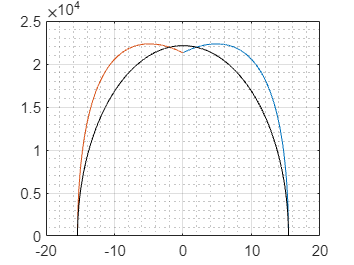

grid on
grid minor


hold off

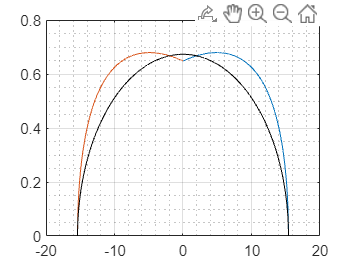


plot(semispan*cos(thetadist),Cl_plot)
hold on
plot(-semispan*cos(thetadist),Cl_plot)

plot(-semispan*cos(thetadist),Cl_ellipse_plot,'k')
plot(semispan*cos(thetadist),Cl_ellipse_plot,'k')
grid on
grid minor


hold off


MACind = find(c_y == MACpos)

MACind =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


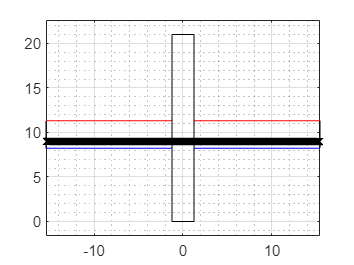

longitudinalMACac =  9;
fuselagedatum = 0;
feselageend = 21;


% plot(span_disc,c_y,'.')
% x_engine = quarterchord(ceil(length(c_y)*0.37))
% height_engine0.37*max(span_disc)*tand(5)-0.175*c_y(ceil(length(c_y)*0.37))-0.9
LEsweep = (quarterchord-quarterchord(MACind) + longitudinalMACac) - 0.25 .* c_y;
TEsweep = (quarterchord-quarterchord(MACind) + longitudinalMACac) + 0.75 .* c_y;
quarterchordplot = (quarterchord-quarterchord(MACind) + longitudinalMACac);
%origin at quarterchord point of root chord
plot (span_disc(floor(fuselage_rad*1/discret):end),LEsweep(floor(fuselage_rad*1/discret):end),'b')
hold on
plot (span_disc(floor(fuselage_rad*1/discret):end),TEsweep(floor(fuselage_rad*1/discret):end),'r')
plot (span_disc(floor(fuselage_rad*1/discret):end),quarterchordplot(floor(fuselage_rad*1/discret):end),'g')
plot (span_disc(MACind),quarterchordplot(MACind),'xk')

plot (-span_disc(floor(fuselage_rad*1/discret):end),TEsweep(floor(fuselage_rad*1/discret):end),'r')
hold on
plot (-span_disc(floor(fuselage_rad*1/discret):end),LEsweep(floor(fuselage_rad*1/discret):end),'b')
plot (-span_disc(floor(fuselage_rad*1/discret):end),quarterchordplot(floor(fuselage_rad*1/discret):end),'g')
plot (-span_disc(MACind),quarterchordplot(MACind),'xk')

plot ([span_disc(floor(fuselage_rad*1/discret)),span_disc(floor(fuselage_rad*1/discret))], [LEsweep(floor(fuselage_rad*1/discret)),TEsweep(floor(fuselage_rad*1/discret))],'k')
plot ([span_disc(end),span_disc(end)], [LEsweep(end),TEsweep(end)],'k')
plot ([-span_disc(floor(fuselage_rad*1/discret)),-span_disc(floor(fuselage_rad*1/discret))], [LEsweep(floor(fuselage_rad*1/discret)),TEsweep(floor(fuselage_rad*1/discret))],'k')
plot ([-span_disc(end),-span_disc(end)], [LEsweep(end),TEsweep(end)],'k')

plot ([span_disc(floor(fuselage_rad*1/discret)),span_disc(floor(fuselage_rad*1/discret))],[fuselagedatum,feselageend],'k')
plot ([-span_disc(floor(fuselage_rad*1/discret)),-span_disc(floor(fuselage_rad*1/discret))],[fuselagedatum,feselageend],'k')
plot ([-span_disc(floor(fuselage_rad*1/discret)),span_disc(floor(fuselage_rad*1/discret))],[fuselagedatum,fuselagedatum],'k')
plot ([-span_disc(floor(fuselage_rad*1/discret)),span_disc(floor(fuselage_rad*1/discret))],[feselageend,feselageend],'k')


axis equal
hold off
grid on
grid minor

chordpos = 0;

Cl_alpha = 6.68

Cl_alpha = 6.6800

Mach = 0.45

Mach = 0.4500

S_rat = (Sref-2*fuselage_rad*c_y(fuselage_rad*100))/Sref

S_rat = 0.9188

FLF = 1.07*(1+(2*fuselage_rad/(semispan*2)))^2

FLF = 1.2508

yetaest = 0;
CL_alpha_curve = easyCLcurve(Cl_alpha, Mach, Sweep, AR, S_rat, FLF,yetaest)

CL_alpha_curve = 6.2162


V_stall = sqrt(WS*2/(rho*2.7))

V_stall = 80.6351

function [Sref, c_y,span_disc,quarterchord,MACpos,c_bar,span] = planformcalc(AR, Sweep, Taper, Sref, discret)
%(AR, Sweep, Taper, c_bar) 
span = sqrt(AR * Sref);
c_bar = Sref/span;
span_disc = [0:discret:span/2];
syms croot;
eqn = (croot+Taper*croot)*(span/2) == Sref;
croot = double(solve(eqn,croot));
c_y =  (Taper-1)*croot/(span/2).*span_disc + croot;
MACposind = find(abs(c_y-c_bar) == min(abs(c_y-c_bar)));
MACpos = c_y(MACposind);
quarterchord =  span_disc .* tand(Sweep);


% s_1 = 0.25 * AR * (1+Taper); %_1 using 1 as reference root chord length
% Sref_1 = (1 + Taper) * s_1;
% span_disc_1 = [0:0.01:s_1];
% c_y_1 = 1 - ((1-Taper)/s_1) * span_disc_1;
% c_bar_1 = 2*trapz(span_disc_1,(c_y_1).^2)/Sref_1;
% ratio = c_bar/c_bar_1; % dimensionalize using c_bar, can be changed later to root or tip chord length
% s = ratio*s_1;
% Sref = ratio * (1 + Taper) * s;
% span_disc = [0:0.01:s];
% c_y =  (1 - ((1-Taper)/s) * span_disc)*ratio;
% temp1 = (c_y - c_bar).^2;
% MACpos = find(temp1 == min(temp1));
% quarterchord =  span_disc .* tand(Sweep);
end
function [CL_alpha_curve] = easyCLcurve(Cl_alpha, Mach, Sweep, AR, S_rat, FLF,yetaest)
beta = (1-Mach^2)^0.5;
if yetaest == 0
    yeta = Cl_alpha/(2*pi/beta);
else
    yeta = yetaest;
end
CL_alpha_curve = 2*pi*AR/(2+(4+((AR^2*beta^2)/(yeta^2))*(1+(tand(Sweep))^2/(beta^2)))^0.5) * S_rat * FLF;
end